test = load('D:\Bristol\23-24\Individual Project\20240410_2\Rx2\4QAM\my_difference.mat','my_record_diff')

test = 包含以下字段的 struct :
    my_record_diff: [15×10 double]


test1 = load('D:\Bristol\23-24\Individual Project\20240410_2\Rx2\4QAM\my_difference1.mat','my_record_diff')

test1 = 包含以下字段的 struct :
    my_record_diff: [15×10 double]


my_perc_diff = test.my_record_diff

my_perc_diff =     0.1179    0.0899    0.1106    0.1045    0.1084    0.1229    0.1151    0.1235    0.1145    0.1134
    0.1006    0.0480    0.0698    0.0447    0.0844    0.0816    0.0810    0.0838    0.0598    0.0765
    0.0229    0.0251    0.0374    0.0291    0.0391    0.0313    0.0307    0.0369    0.0285    0.0196
    0.0140    0.0073    0.0073    0.0084    0.0073    0.0106    0.0078    0.0112    0.0067    0.0134
    0.0028    0.0050    0.0022    0.0056    0.0039    0.0039    0.0095    0.0017    0.0039    0.0045
    0.0028    0.0017    0.0006    0.0011    0.0006    0.0028    0.0017    0.0017    0.0006    0.0022
    0.0011    0.0017    0.0011         0    0.0011    0.0006    0.0017    0.0006    0.0011    0.0017
    0.0017    0.0011    0.0006    0.0011    0.0011    0.0006    0.0006    0.0022    0.0028    0.0006
    0.0006    0.0011    0.0011    0.0017    0.0017    0.0006    0.0006    0.0017    0.0011    0.0011
    0.0011    0.0017    0.0011    0.0022    0.0017    0.0022    0.0022    0.

my_perc_diff1 = test1.my_record_diff

my_perc_diff1 =     0.3782    0.3045    0.3006    0.3665    0.4011    0.4162    0.3363    0.4989    0.3944    0.4112
    0.3425    0.2106    0.2229    0.3425    0.3011    0.3106    0.2676    0.3173    0.2709    0.3117
    0.2536    0.1425    0.1480    0.2257    0.2039    0.1704    0.1592    0.2240    0.2358    0.2771
    0.1240    0.0804    0.0737    0.1911    0.1117    0.1263    0.1480    0.1341    0.1486    0.1676
    0.1067    0.0603    0.0782    0.1106    0.1056    0.0899    0.0665    0.1017    0.1145    0.0961
    0.1061    0.0408    0.0385    0.0615    0.0933    0.0419    0.0525    0.0587    0.0637    0.0693
    0.0274    0.0073    0.0268    0.0469    0.0330    0.0346    0.0190    0.1022    0.0402    0.0363
    0.0073    0.0034    0.0050    0.0190    0.0223    0.0117    0.0123    0.0279    0.0201    0.0246
    0.0084    0.0039    0.0056    0.0084    0.0335    0.0173    0.0190    0.0128    0.0123    0.0212
    0.0073    0.0050    0.0117    0.0112    0.0168    0.0106    0.0156    0

n = size(my_perc_diff, 2);
rowMeans = (1/n) * my_perc_diff * ones(n, 1) %caculate the average

rowMeans =     0.1121
    0.0730
    0.0301
    0.0094
    0.0043
    0.0016
    0.0011
    0.0012
    0.0011
    0.0016


rowMeans1 = (1/n) * my_perc_diff1 * ones(n, 1) 

rowMeans1 =     0.3808
    0.2898
    0.2040
    0.1306
    0.0930
    0.0626
    0.0374
    0.0154
    0.0142
    0.0135


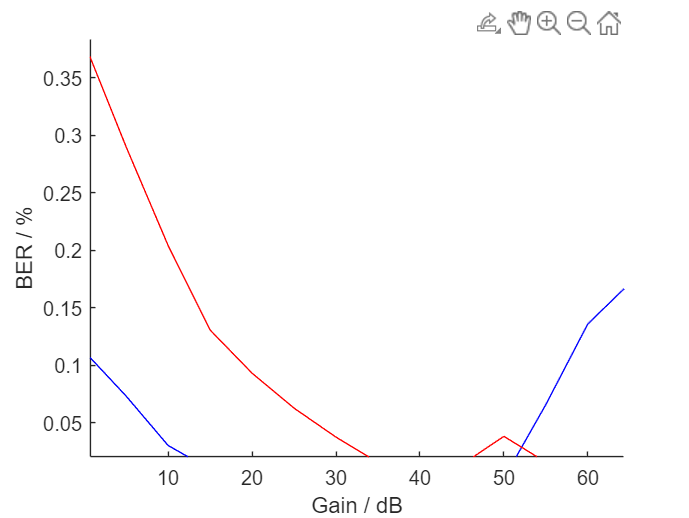


figure();
hold on;
xlabel('Gain / dB')
ylabel('BER / %')
plot(0:5:70,rowMeans,'b')
plot(0:5:70,rowMeans1,'r')
hold off